load current meter record from the Alenuihaha Channel off the Island of Hawaii

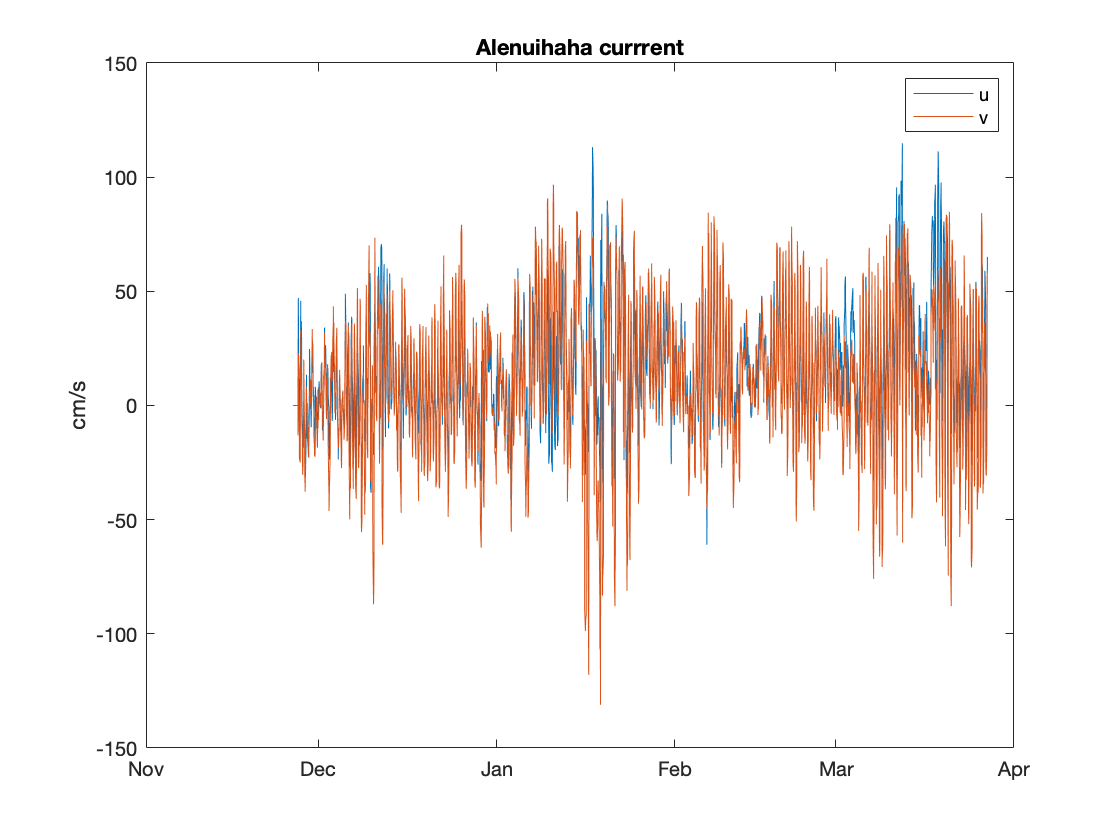

load uv_alenuihaha

figure (1)
plot(t,u,t,v)
datetick
ylabel('cm/s')
legend('u','v')
title('Alenuihaha currrent')

Scatter plot

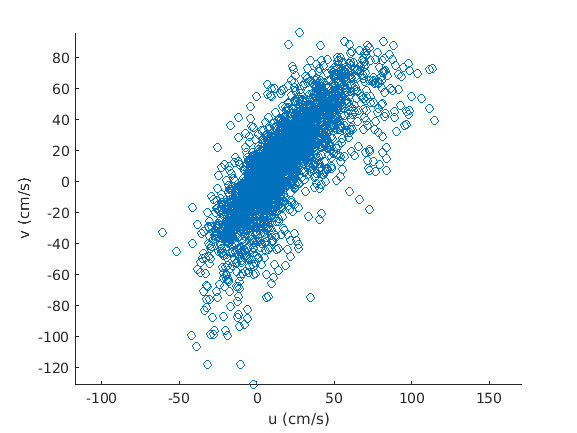

figure (2)
scatter(u,v)
xlabel('u (cm/s)')
ylabel('v (cm/s)')
axis('equal')

We want to make the axis through the data the principal axis which also maximzes covariance/variance?

Compute covariance matrix - time average

nt = length(t);
uc = [detrend(u,0),detrend(v,0)];
C = 1/(nt-1)*(uc'*uc)

C =   610.9132  615.0149
  615.0149  997.8709


diag = (variances 1,1 = uu ; 2,2 = vv)


% columns = eigenvectors, lambdas = eigenvalues

Compute EOF

[e,lambda] = eig(C); % ascending or descending eigenvalues ( lambda ) % here we're descneding (lowest to highest value) we want ascending, flip later
e

e =    -0.8063    0.5916
    0.5916    0.8063


lambda = diag(lambda)

lambda = 	1.0e+03 *

    0.1597
    1.4491


e = fliplr(e); % flip matrix 
lambda = flipud(lambda);

A = uc*e; % projecting eigenvectors on data 

Plot temporal expansion

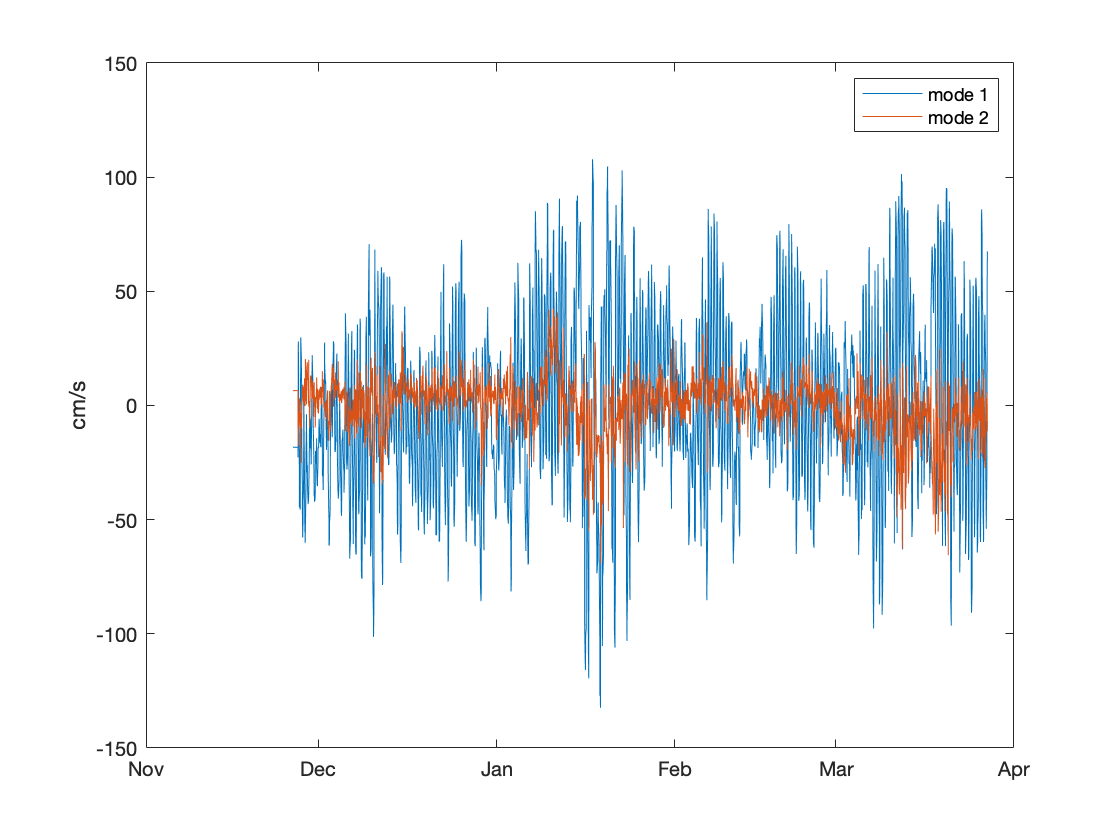

plot(t,A(:,1),t,A(:,2))
datetick
ylabel('cm/s')
legend('mode 1','mode 2')

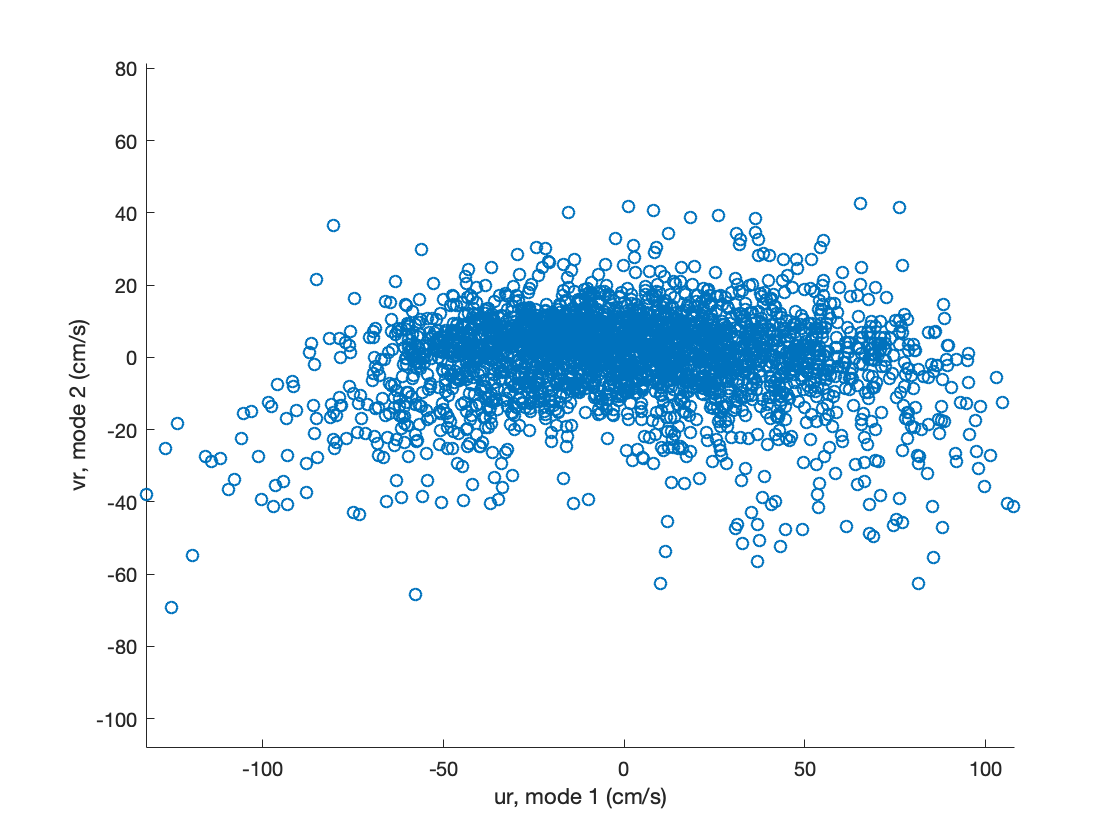

scatter(A(:,1),A(:,2))
axis('equal')
xlabel('ur, mode 1 (cm/s)')
ylabel('vr, mode 2 (cm/s)')

## Relationship between eigenfunctions and a rotation matrix


$$R\left(\theta \right)=\left\lbrack \begin{array}{cc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{cos}\theta 
\end{array}\right\rbrack$$


Rotation matrix rotates a column vector by angle $\theta$ 


$$\left\lbrack \begin{array}{c}
\mathrm{xr}\\
\mathrm{yr}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{cos}\theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$$


For our example, 

A = uc*e;

e is equivalent to the rotation matrix, and A contains the rotated currents

In the above example, the rotation angle is

ang = acos(e(1,1))

ang = 0.9378

ang = -asin(e(1,2))

ang = 0.9378

ang_deg = ang*180/pi

ang_deg = 53.7316

## Eigenfunctions and diagonalizing a matrix

A square matrix C is diagnolizable if there exists an invertible matrix e (column vectors gholding eigenvectors) and a diagonal Matric lambda (diag(lambda)) such that S^-1AS = D


$$C=e\;\lambda \;e^{-1}$$


$e$ = eigenvectors

$\lambda$ = eigenvalues

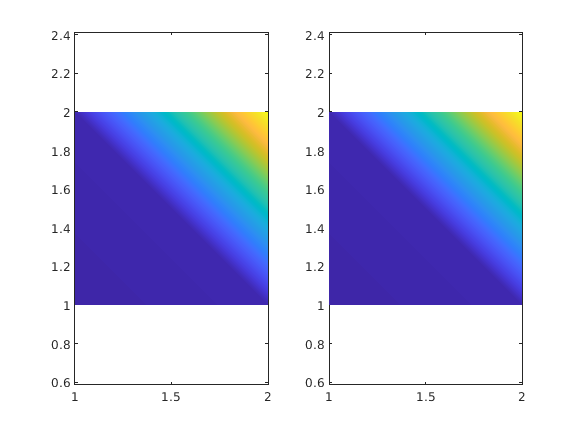

[e,lambda] = eig(C);
C2 = e*lambda*inv(e);
subplot(121)
pcolor(C)
shading interp
axis('equal')
subplot(122)
pcolor(C2)
shading interp
axis('equal')